# Difference of Gaussians

## How it works

A gaussian blur is applied to an image two times and the difference of them is taken. The result is an image with its edges highlighted.

### 
$$G_{\sigma } -G_{k\sigma }$$


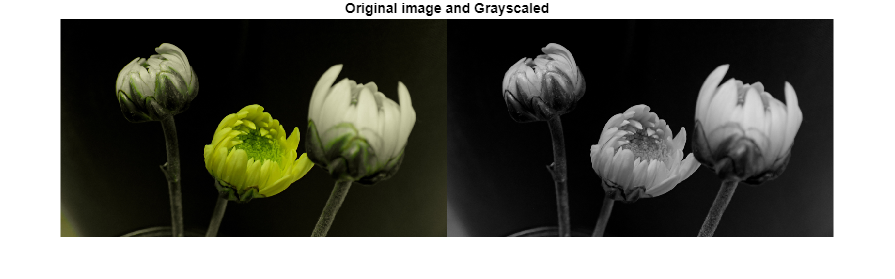

buds = imread("assets\images\blooming_buds.jpg");

% convert to grayscale image between [0 1]
gray_buds = double(rgb2gray(buds))/255.0;
montage({buds, gray_buds});
title("Original image and Grayscaled");

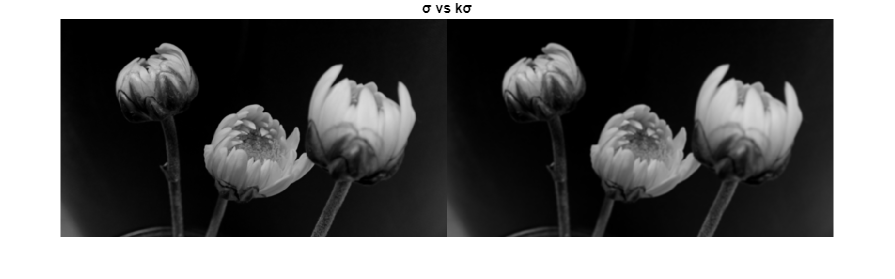

sigma =5; % sigma (σ)
k = 1.6;
G_sig = imgaussfilt(gray_buds, sigma);
G_k_sig = imgaussfilt(gray_buds, k*sigma);
dog = G_sig - G_k_sig;
montage({G_sig, G_k_sig});
title("σ vs kσ");

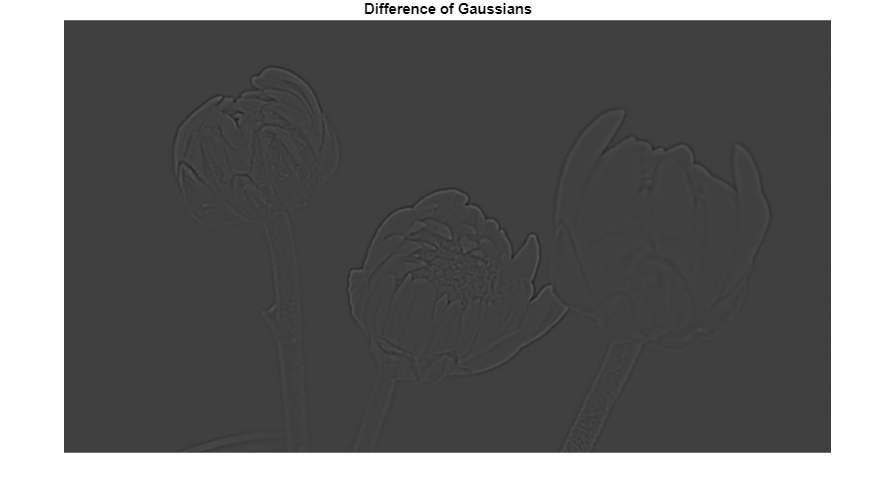

% the DoG exposure is increased by 0.25 to better see the result
imshow(dog + 0.25);
title("Difference of Gaussians");

We can apply a threshold which results in a binary image.

### 
$$T_{\varepsilon } \left(u\right)=\left\lbrace \begin{array}{ll}
1 & u\ge \varepsilon \\
0 & \mathrm{otherwise}
\end{array}\right.$$


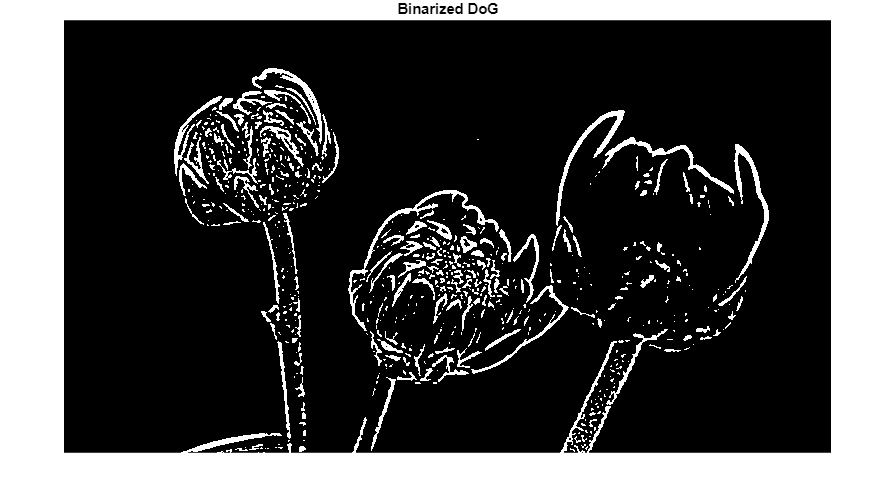

% Threshold
thresh =0.00625; % epsilon (ε)
bin_dog = dog;
bin_dog(bin_dog >= thresh) = 1;
bin_dog(bin_dog < thresh) = 0;

imshow(bin_dog);
title("Binarized DoG");

clear dog bin_dog buds gray_buds;

# XDoG: An eXtended Difference-of-Gaussians used for advanced image styization

We continue from the Difference of Gaussians and try to generalize and extend it in an aesthetic way. We try to derive some styles such as pencil-shading, pastel, hatching and woodcut as well as a range of subtle artistic effects.

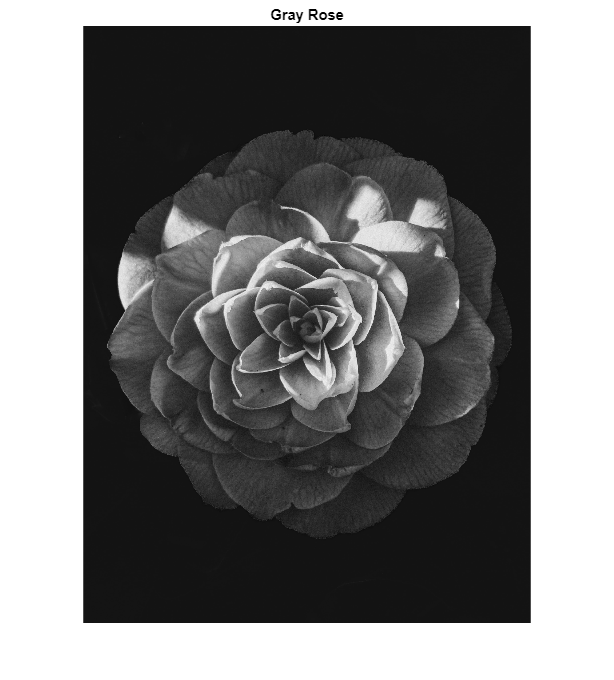

gray_rose = imread("assets\images\gray_rose.jpg");
gray_rose = double(rgb2gray(gray_rose))/255.0;
imshow(gray_rose);
title("Gray Rose");

### Edge emphasis stregnth

We start by introducing $\tau$ (tau) as a scalar to the ${\mathit{\mathbf{G}}}_{\mathit{\mathbf{k}}\sigma }$

### 
$$G_{\sigma } -\tau \cdot G_{k\sigma }$$


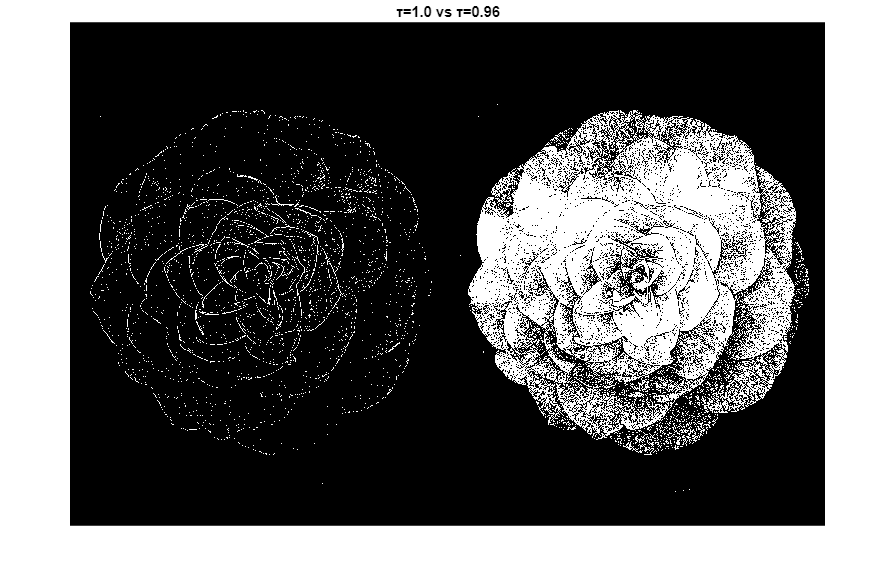

sigma =1.4; % sigma (σ)
tau =0.96; % tau (τ)
k = 1.6;

G_sig = imgaussfilt(gray_rose, sigma);
G_k_sig = imgaussfilt(gray_rose, k*sigma);

dog_1 = G_sig - 1.0*G_k_sig;
dog_tau = G_sig - tau*G_k_sig;

% Binary Threshold
eps =0.0075; % epsilon (ε)
dog = [dog_1, dog_tau];
dog(dog >= eps) = 1;
dog(dog < eps) = 0;

imshow(dog);
title(sprintf("τ=1.0 vs τ=%.2f", tau));

### Smooth thresholding

We can use a smooth thresholding function

### 
$$T_{\varepsilon ,\varphi } \left(u\right)=\left\lbrace \begin{array}{ll}
1 & u\ge \varepsilon \\
1+\tanh \left(\varphi \cdot \left(u-\varepsilon \right)\right) & \mathrm{otherwise}
\end{array}\right.$$


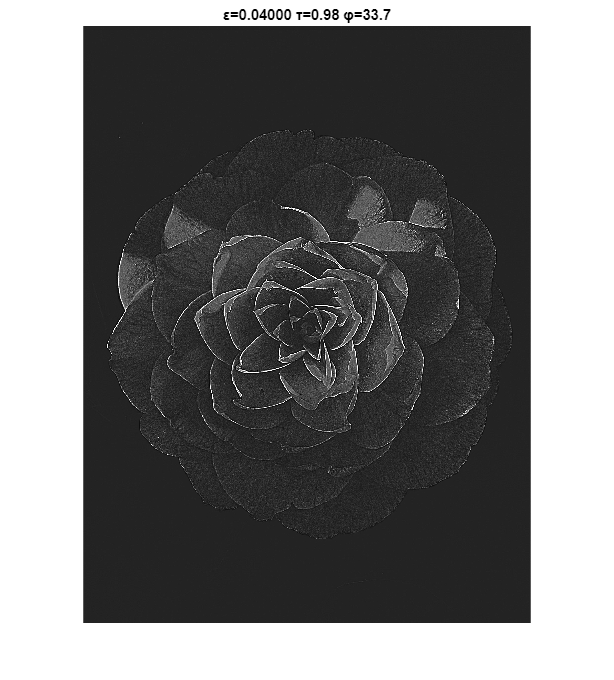

eps =0.04; % epsilon (ε)
phi =33.7; % phi (φ)
tau =0.98; % tau (τ)

% Smooth Threshold
dog = G_sig - tau*G_k_sig;
dog(dog >= eps) = 1;
dog(dog < eps) = 1 + tanh(phi*(dog(dog < eps) - eps));
imshow(dog);
title(sprintf("ε=%.5f τ=%.2f φ=%.1f",eps, tau, phi));

### Reparameterization for better control

As we increase $\tau$ the average brightness of the image decresses. However increasing $\tau$ is the only way of increasing emphasis on edge lines. Thus, in order to create XDoG outputs having different edge emphasis strengths but same average brightness, any adjustments to $\tau$ must be coupled with adjusting $\varphi$ and $\varepsilon$.

After reparameterization we derive this eqation:

### 
$$\left(1+p\right){\cdot G}_{\sigma } -p\cdot G_{k\sigma }$$


Refer to `eXtended_difference_of_gaussians` eqation 7 reference for more information.

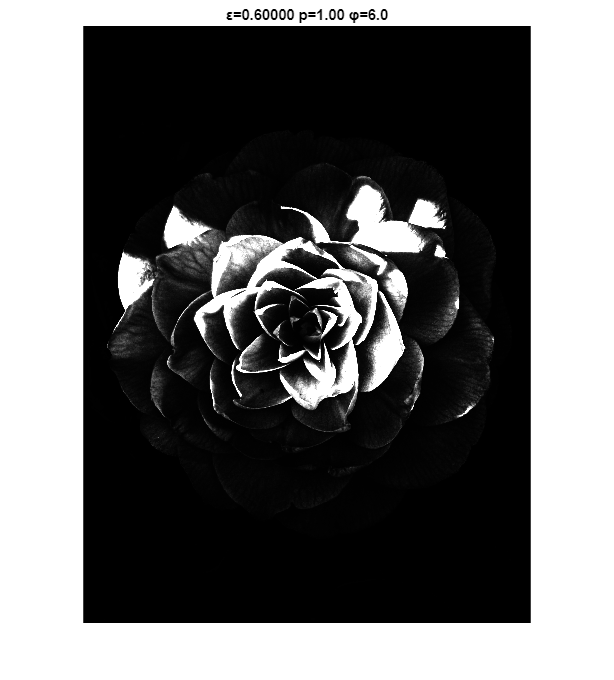

eps =0.6; % epsilon (ε)
phi =6; % phi (φ)
p =1; % p

% Smooth Threshold
dog = (1+p)*G_sig - p*G_k_sig;
dog(dog >= eps) = 1;
dog(dog < eps) = 1 + tanh(phi*(dog(dog < eps) - eps));
imshow(dog);
title(sprintf("ε=%.5f p=%.2f φ=%.1f",eps, p, phi));